# MSessionExplorer.SliceSession

Ignore code in this section

if exist('isRun', 'var') && exist('seRaw', 'var') && isRun
    se = seRaw.Duplicate;
    se.isVerbose = false;
    se.SetColumn('adc', 'tubeV', @(x) x-median(x), 'each')
else
    edit MSessionExplorer.Examples.SliceSession
    return;
end

**Description**

help MSessionExplorer.SliceSession

  Slice session into a different set of epochs
  
    SliceSession(tSlice, tType)
 
  Inputs
    tSlice      A vector of times at which slicing occurs. Note that data before the first slicing 
                time will be irreversibly discarded. 
                If refType is 'relative', tSlice can be a scalar which is used by all epochs, or 
                a vector whose length matches the number epoch. 
                If refType is 'absolute', tSlice can be a vector of arbitrary length. 
    tType       'absolute' or 'relative', indicating whether tSlice represents absolute times in 
                the session or is relative to epoch reference times. If using 'absolute', existing 
                epoch sorting, time alignment and all eventValues table will be lost due to an 
                unknown relationship between current and new epochs. New data will sort epochs in 
                temporal order and align epoch time to respective tSlice. 



**Example 1**

**Adjust the slicing time of each epoch using the 'relative' option**

First, let's see how epochs are currently sliced. The plotted are the first 10 epochs in this session. Magenta dots show 'lickOn' events from 'behavTime' table. Lines show 'tubeV' time series from 'adc' table. 

In this particular example, data in each epoch happens to begin at zero epoch time and ends before the zero time of the next epoch. Remember that epochs' zero times and the reference times in a session are the same physical times but expressed with a relative versus absolute frame of reference. 

se.Preview('behavTime', 'adc')

    cue      posIndex      water    opto       lickOn           lickOff   
    ___    ____________    _____    ____    _____________    _____________

     0     [6×1 double]    1.832    NaN     [20×1 double]    [20×1 double]
     0     [6×1 double]    1.788    NaN     [19×1 double]    [19×1 double]
     0     [6×1 double]     1.87    NaN     [21×1 double]    [21×1 double]
     0     [6×1 double]    1.755    NaN     [16×1 double]    [16×1 double]
     0     [6×1 double]    1.891    NaN     [16×1 double]    [16×1 double]
     0     [6×1 double]    1.742    NaN     [14×1 double]    [14×1 double]

          time             lickportV           lickportH             tubeV               tubeH      
    

se.GetReferenceTime()'

ans = 	1.0e+03 *

    0.0504    0.0638    0.0754    0.0898    0.0985    0.1081    0.1176    0.1270    0.1342    0.1459    0.1529    0.1621    0.1697    0.1855    0.1932    0.2058    0.2128    0.2197    0.2329    0.2442    0.2515    0.2651    0.2725    0.2972    0.3041    0.3138    0.3249    0.3350    0.3435    0.3553    0.3633    0.3704    0.3775    0.3903    0.4030    0.4101    0.4182    0.4314    0.4395    0.4524    0.4599    0.4668    0.4738    0.4880    0.4954    0.5071    0.5150    0.5258    0.5328    0.5619


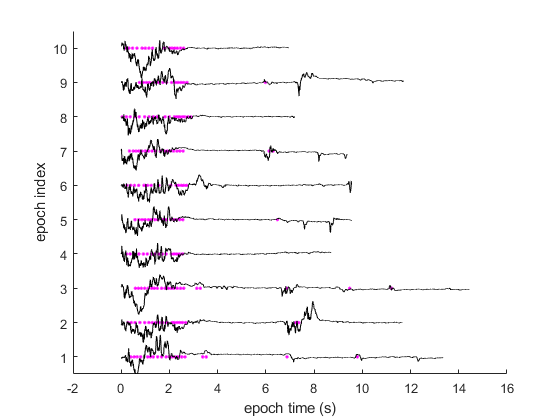

Visualize(se);

Let's move the slicing times 1 second earlier than the current zero epoch times. 

se.SliceSession(-1, 'relative');

Now, the data begins at -1s epoch time and ends before the -1s of the next epoch. (Btw, there is no data available before the first epoch.) Although epochs were resliced, note that the time stamps of events and samples were the same as before. 

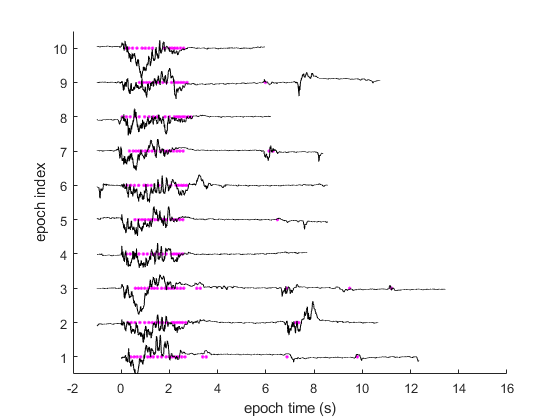

Visualize(se);

We can adjust the slicing times differently for each epoch. Here uses sine wave function to generate variable shifts, for no particular reason. 

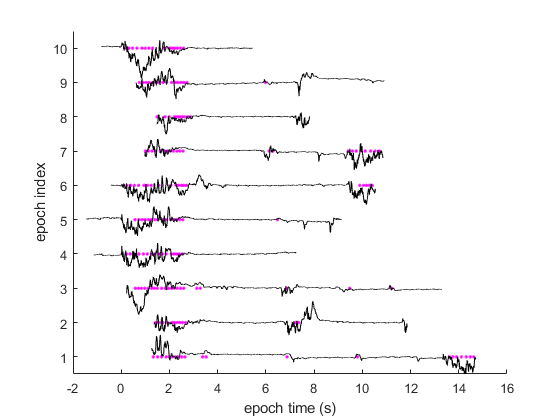

tSlice = sin(1:se.numEpochs)*1.5;

seCopy = se.Duplicate; % make a copy to work on

seCopy.SliceSession(tSlice, 'relative');

Visualize(seCopy);

Finally, we slice the session back to how it began - sliced at zero epoch times. 

seCopy.SliceSession(0, 'relative');

Everything looks the same as before except that part of data at the beginning of the first epoch is missing. It is because, in the last setp, that portion was sliced out but there was no epoch before the first one to receive it, and was permanently lost. (A future version may force to include all data.)

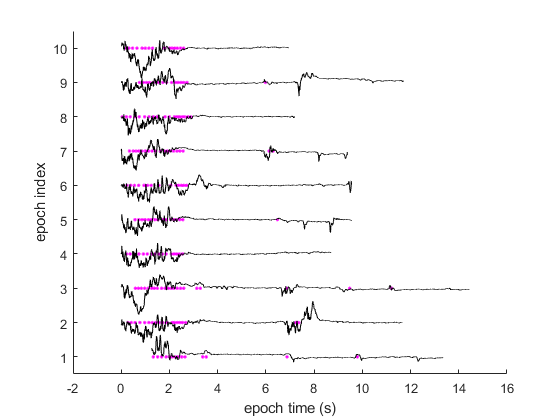

Visualize(seCopy);

**Example 2**

**Slice session into arbitrary number of epochs using 'absolute' option**

Slice the session into a certain number of 14-second long epochs. 

tRef = se.GetReferenceTime()'

tRef = 	1.0e+03 *

    0.0504    0.0638    0.0754    0.0898    0.0985    0.1081    0.1176    0.1270    0.1342    0.1459    0.1529    0.1621    0.1697    0.1855    0.1932    0.2058    0.2128    0.2197    0.2329    0.2442    0.2515    0.2651    0.2725    0.2972    0.3041    0.3138    0.3249    0.3350    0.3435    0.3553    0.3633    0.3704    0.3775    0.3903    0.4030    0.4101    0.4182    0.4314    0.4395    0.4524    0.4599    0.4668    0.4738    0.4880    0.4954    0.5071    0.5150    0.5258    0.5328    0.5619


tSlice = tRef(1) : 14 : tRef(end)

tSlice = 	1.0e+03 *

    0.0504    0.0644    0.0784    0.0924    0.1064    0.1204    0.1344    0.1484    0.1624    0.1764    0.1904    0.2044    0.2184    0.2324    0.2464    0.2604    0.2744    0.2884    0.3024    0.3164    0.3304    0.3444    0.3584    0.3724    0.3864    0.4004    0.4144    0.4284    0.4424    0.4564    0.4704    0.4844    0.4984    0.5124    0.5264    0.5404    0.5544    0.5684    0.5824    0.5964    0.6104    0.6244    0.6384    0.6524    0.6664    0.6804    0.6944    0.7084    0.7224    0.7364


Now, we slice the session into 203 epochs, which are completely unrelated to the 265 epochs before. That's the reason we see the warning message below. 

seCopy = se.Duplicate; % make a copy to work on

seCopy.SliceSession(tSlice, 'absolute')


seCopy.Preview;

tot
                  tableType        tableData       referenceTime 
                 ____________    ______________    ______________

    behavTime    'eventTimes'    [203×6  table]    [203×1 double]
    hsv          'timeSeries'    [203×4  table]    [203×1 double]
    adc          'timeSeries'    [203×5  table]    [203×1 double]
    LFP          'timeSeries'    [203×2  table]    [203×1 double]
    spikeTime    'eventTimes'    [203×58 table]    [203×1 double]

userData
    sessionInfo: [1×1 struct]
        satInfo: [1×1 struct]
        hsvInfo: [1×1 struct]
      intanInfo: [1×1 struct]
    preTaskData: [1×1 struct]
      spikeInfo: [1×1 struct]



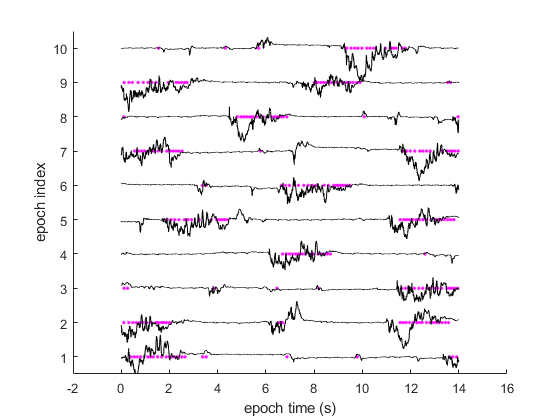

Visualize(seCopy);

As a special use, we can slice the whole session into one epoch. This basically converts data to continuous recordings. 

seCopy.SliceSession(0, 'absolute');

seCopy.Preview;

tot
                  tableType       tableData      referenceTime
                 ____________    ____________    _____________

    behavTime    'eventTimes'    [1×6  table]         [0]     
    hsv          'timeSeries'    [1×4  table]         [0]     
    adc          'timeSeries'    [1×5  table]         [0]     
    LFP          'timeSeries'    [1×2  table]         [0]     
    spikeTime    'eventTimes'    [1×58 table]         [0]     

userData
    sessionInfo: [1×1 struct]
        satInfo: [1×1 struct]
        hsvInfo: [1×1 struct]
      intanInfo: [1×1 struct]
    preTaskData: [1×1 struct]
      spikeInfo: [1×1 struct]



seCopy.Preview('behavTime', 'adc');

         cue             posIndex            water         opto        lickOn             lickOff    
    ______________    _______________    ______________    ____    _______________    _______________

    [265×1 double]    [1590×1 double]    [264×1 double]    NaN     [3878×1 double]    [3878×1 double]

           time               lickportV             lickportH               tubeV                 tubeH       
    __________________    __________________    __________________    __________________    __________________

    [2846160×1 double]    [2846160×1 single]    [2846160×1 single]    [2846160×1 single]    [28

Helper function

function Visualize(se)
[bt, adc] = se.GetTable('behavTime', 'adc');
ind = 1:10;
figure; clf
MPlot.PlotRaster(bt.lickOn(ind), ind, 'Color', 'm');
MPlot.PlotTraceLadder(adc.time(ind), adc.tubeV(ind), ind, 'Color', 'k');
xlim([-2 16]);
ylim([ind(1)-0.5 ind(end)+0.5]);
xlabel('epoch time (s)');
ylabel('epoch index');
box off
end